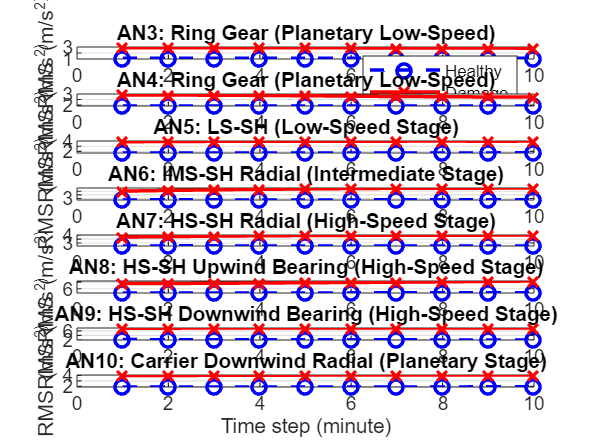

clear; clc; close all;

%% RMS and CF

n_files = 10; % 10 Healthy and 10 Damage datasets
Fs = 40000; % 40 kHz sampling rate

channel_names = {'AN3', 'AN4', 'AN5', 'AN6', 'AN7', 'AN8', 'AN9', 'AN10'};
labels = {...
    'AN3: Ring Gear (Planetary Low-Speed)', ...
    'AN4: Ring Gear (Planetary Low-Speed)', ...
    'AN5: LS-SH (Low-Speed Stage)', ...
    'AN6: IMS-SH Radial (Intermediate Stage)', ...
    'AN7: HS-SH Radial (High-Speed Stage)', ...
    'AN8: HS-SH Upwind Bearing (High-Speed Stage)', ...
    'AN9: HS-SH Downwind Bearing (High-Speed Stage)', ...
    'AN10: Carrier Downwind Radial (Planetary Stage)'};

num_ch = length(channel_names);

rms_H = zeros(n_files, num_ch);   rms_D = zeros(n_files, num_ch); % rms acceleration m/s^2
peak_H = zeros(n_files, num_ch);  peak_D = zeros(n_files, num_ch); % acceleration m/s^2
cf_H = zeros(n_files, num_ch);    cf_D = zeros(n_files, num_ch); % crest factor (CF)

for i = 1:n_files
    file_H = sprintf('H%d.mat', i);
    file_D = sprintf('D%d.mat', i);
    
    % Healthy Dataset
    if exist(file_H, 'file')
        data_H = load(file_H);
        for ch = 1:num_ch
            sig = data_H.(channel_names{ch});
            sig = sig - mean(sig); % De-trend
            rms_H(i, ch) = rms(sig);
            peak_H(i, ch) = max(abs(sig));
            cf_H(i, ch) = peak_H(i, ch)/rms_H(i, ch);
        end
    end
    
    % Damage Dataset
    if exist(file_D, 'file')
        data_D = load(file_D);
        for ch = 1:num_ch
            sig = data_D.(channel_names{ch});
            sig = sig - mean(sig); % De-trend
            rms_D(i, ch) = rms(sig);
            peak_D(i, ch) = max(abs(sig));
            cf_D(i, ch) = peak_D(i, ch)/rms_D(i, ch);
        end
    end
end


% Plots for RMS and crest factor
time_axis = 1:n_files;

% RMS - tracking overall energy changes
figure('Name', 'RMS Acceleration');
for ch = 1:num_ch
    subplot(num_ch, 1, ch);
    plot(time_axis, rms_H(:, ch), '--o', 'Color', "b", 'LineWidth', 1.5); hold on;
    plot(time_axis, rms_D(:, ch), '-x', 'Color', "r", 'LineWidth', 1.5);
    title(labels{ch});
    ylabel('RMS (m/s^2)');
    if ch == 1, legend('Healthy', 'Damage'); end
    if ch == num_ch, xlabel('Time step (minute)'); end
    grid on;
end

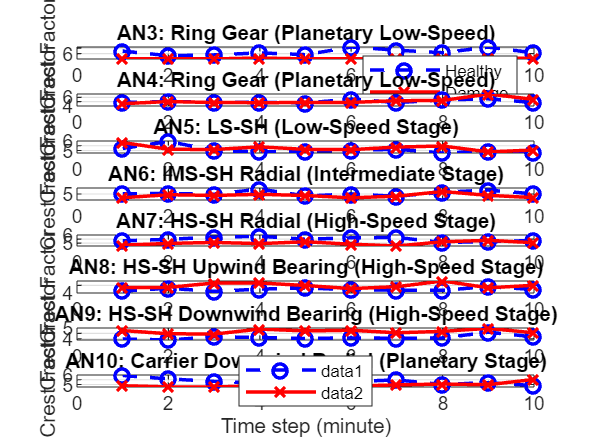


% CF - tracking impulsive changes (dents/cracks)
figure('Name', 'Crest Factor');
for ch = 1:num_ch
    subplot(num_ch, 1, ch);
    plot(time_axis, cf_H(:, ch), '--o', 'Color', "b", 'LineWidth', 1.5); hold on;
    plot(time_axis, cf_D(:, ch), '-x', 'Color', "r", 'LineWidth', 1.5);
    title(labels{ch});
    ylabel('Crest Factor');
    if ch == 1, legend('Healthy', 'Damage'); end
    if ch == num_ch, xlabel('Time step (minute)'); end
    grid on;
end

% RMS increase prominent in AN6 and AN7, CF decrese prominent in AN3 (Healthy vs Damage) 

%% High-Frequency Noise Floor Comparison for AN3 AN4 AN5 AN6 AN7

% high-frequency tracking window 
noise_low = 10000;    % 10 kHz
noise_high = 18000;   % 18 kHz

H_trend = struct('AN3', zeros(n_files,1), 'AN4', zeros(n_files,1), 'AN5', zeros(n_files,1), 'AN6', zeros(n_files,1), 'AN7', zeros(n_files,1));
D_trend = struct('AN3', zeros(n_files,1), 'AN4', zeros(n_files,1), 'AN5', zeros(n_files,1), 'AN6', zeros(n_files,1), 'AN7', zeros(n_files,1));

for i = 1:n_files
    file_H = sprintf('H%d.mat', i);
    data_H = load(file_H);
    H_trend.AN3(i) = get_noise(data_H.AN3, Fs, noise_low, noise_high);
    H_trend.AN4(i) = get_noise(data_H.AN4, Fs, noise_low, noise_high);
    H_trend.AN5(i) = get_noise(data_H.AN5, Fs, noise_low, noise_high);
    H_trend.AN6(i) = get_noise(data_H.AN6, Fs, noise_low, noise_high);
    H_trend.AN7(i) = get_noise(data_H.AN7, Fs, noise_low, noise_high);
end

for i = 1:n_files
    file_D = sprintf('D%d.mat', i);
    data_D = load(file_D);
    D_trend.AN3(i) = get_noise(data_D.AN3, Fs, noise_low, noise_high);
    D_trend.AN4(i) = get_noise(data_D.AN4, Fs, noise_low, noise_high);
    D_trend.AN5(i) = get_noise(data_D.AN5, Fs, noise_low, noise_high);
    D_trend.AN6(i) = get_noise(data_D.AN6, Fs, noise_low, noise_high);
    D_trend.AN7(i) = get_noise(data_D.AN7, Fs, noise_low, noise_high);
end

% Plot
legend('Location', 'best'); file_axis = 1:n_files;

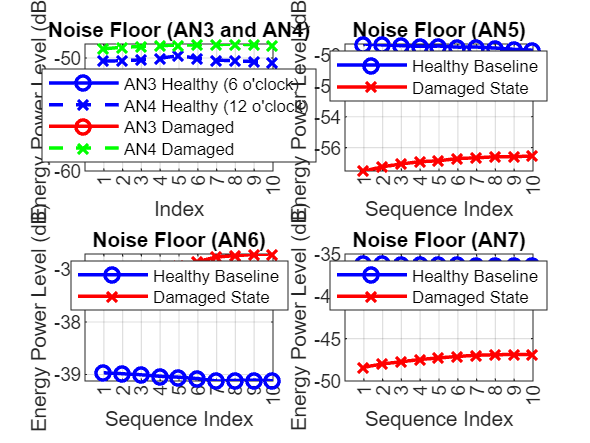

figure('Name', 'Noise floor comparison');
% AN3 and AN4
subplot(2,2,1);
plot(file_axis, 10*log10(H_trend.AN3), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'AN3 Healthy (6 o''clock)'); hold on;
plot(file_axis, 10*log10(H_trend.AN4), 'b--x', 'LineWidth', 1.5, 'DisplayName', 'AN4 Healthy (12 o''clock)'); hold on;
plot(file_axis, 10*log10(D_trend.AN3), 'r-o', 'LineWidth', 1.5, 'DisplayName', 'AN3 Damaged'); hold on;
plot(file_axis, 10*log10(D_trend.AN4), 'g--x', 'LineWidth', 1.5, 'DisplayName', 'AN4 Damaged');
grid on; title('Noise Floor (AN3 and AN4)');
xlabel('Index'); ylabel('Energy Power Level (dB)');
legend('Location', 'best'); xticks(file_axis);

% AN5
subplot(2,2,2);
plot(file_axis, 10*log10(H_trend.AN5), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Healthy Baseline'); hold on;
plot(file_axis, 10*log10(D_trend.AN5), 'r-x', 'LineWidth', 1.5, 'DisplayName', 'Damaged State');
grid on; title('Noise Floor (AN5)');
xlabel('Sequence Index'); ylabel('Energy Power Level (dB)');
legend('Location', 'best'); xticks(file_axis);

% AN6
subplot(2,2,3);
plot(file_axis, 10*log10(H_trend.AN6), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Healthy Baseline'); hold on;
plot(file_axis, 10*log10(D_trend.AN6), 'r-x', 'LineWidth', 1.5, 'DisplayName', 'Damaged State');
grid on; title('Noise Floor (AN6)');
xlabel('Sequence Index'); ylabel('Energy Power Level (dB)');
legend('Location', 'best'); xticks(file_axis);

% AN7
subplot(2,2,4);
plot(file_axis, 10*log10(H_trend.AN7), 'b-o', 'LineWidth', 1.5, 'DisplayName', 'Healthy Baseline'); hold on;
plot(file_axis, 10*log10(D_trend.AN7), 'r-x', 'LineWidth', 1.5, 'DisplayName', 'Damaged State');
grid on; title('Noise Floor (AN7)');
xlabel('Sequence Index'); ylabel('Energy Power Level (dB)');
legend('Location', 'best'); xticks(file_axis);


% Diagnosis
evaluate_real_health('Ring Gears (AN3)', mean(D_trend.AN3)/mean(H_trend.AN3));

Ring Gears (AN3) -> Ratio: 0.76x | Status: NORMAL RANGE


evaluate_real_health('Ring Gears (AN4)', mean(D_trend.AN4)/mean(H_trend.AN4));

Ring Gears (AN4) -> Ratio: 1.33x | Status: INTERMEDIATE DAMAGE DETECTED


evaluate_real_health('Low-Speed Parallel Stage Gear Set (AN5)', mean(D_trend.AN5)/mean(H_trend.AN5));

Low-Speed Parallel Stage Gear Set (AN5) -> Ratio: 0.18x | Status: FAULT/STRUCTURAL DAMAGE DETECTED


evaluate_real_health('Intermediate Parallel Stage Gear Set (AN6)', mean(D_trend.AN6)/mean(H_trend.AN6));

Intermediate Parallel Stage Gear Set (AN6) -> Ratio: 1.63x | Status: INTERMEDIATE DAMAGE DETECTED


evaluate_real_health('High-Speed Parallel Stage Gear Set (AN7)  ', mean(D_trend.AN7)/mean(H_trend.AN7));

High-Speed Parallel Stage Gear Set (AN7)   -> Ratio: 0.08x | Status: FAULT/STRUCTURAL DAMAGE DETECTED


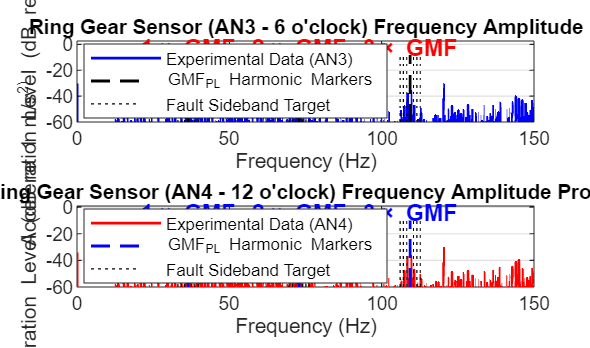


%% Planetary Gearbox Defect Detection - AN3 and AN4

f_carrier = 22.09/60;      % Carrier frequency = 0.3682 Hz (from 22.09 RPM) 
N_ring = 99;                 % Ring gear teeth count 
N_planets = 3;               % Standard planet count for given NREL gearbox

GMF_PL = f_carrier*N_ring; % Planetary Mesh Frequency (~36.45 Hz)
f_pass = f_carrier*N_planets; % Planet passing frequency (~1.105 Hz)

load('D10.mat'); 

% Resampling (Decimation) 
decimation_factor = 40; 
Fs = Fs/decimation_factor; % New sampling rate = 1000 Hz
AN3_dec = decimate(AN3, decimation_factor);
AN4_dec = decimate(AN4, decimation_factor);
N_samples = length(AN3_dec);
window = hanning(N_samples); 

% FFT
fft_AN3 = fft(AN3_dec.*window);
fft_AN4 = fft(AN4_dec.*window);


frequencies = (0:N_samples-1)*(Fs/N_samples);% single-sided magnitude spectrum
cutoff_idx = floor(N_samples/2);

mag_AN3 = abs(fft_AN3(1:cutoff_idx))/N_samples*2;
mag_AN4 = abs(fft_AN4(1:cutoff_idx))/N_samples*2;
f_axis = frequencies(1:cutoff_idx);

% Scaling
db_AN3 = 20*log10(mag_AN3 + eps); % eps prevents log10(0) errors
db_AN4 = 20*log10(mag_AN4 + eps);

db_floor = -60; 

% Plot
figure('Color', [1 1 1], 'Position', [100 100 1100 650]);

% AN3 (6 o'clock)
subplot(2,1,1);
h1 = plot(f_axis, db_AN3, 'b', 'LineWidth', 1.2, 'DisplayName', 'Experimental Data (AN3)'); hold on;
grid on; xlim([0 150]); ylim([db_floor max(db_AN3)+10]);
title('Ring Gear Sensor (AN3 - 6 o''clock) Frequency Amplitude');
xlabel('Frequency (Hz)'); ylabel('Acceleration Level (dB re 1 m/s^2)');

% flag indicators for 1x, 2x, and 3x Mesh Harmonics
h2 = stem(GMF_PL, max(db_AN3)*1.1, 'k--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor, 'DisplayName', 'GMF_{PL} Harmonic Markers');
stem(2*GMF_PL, max(db_AN3)*1.1, 'k--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor);
stem(3*GMF_PL, max(db_AN3)*1.1, 'k--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor);

text(GMF_PL, max(db_AN3)+3, '1\times GMF', 'HorizontalAlignment', 'center', 'Color', 'r', 'FontWeight', 'bold');
text(2*GMF_PL, max(db_AN3)+3, '2\times GMF', 'HorizontalAlignment', 'center', 'Color', 'r', 'FontWeight', 'bold');
text(3*GMF_PL, max(db_AN3)+3, '3\times GMF', 'HorizontalAlignment', 'center', 'Color', 'r', 'FontWeight', 'bold');

% Draw indicator lines for Modulation Sidebands flanking all three harmonic orders
for harmonic = 1:3
    base_freq = harmonic*GMF_PL;
    for i = -3:3
        if i ~= 0
            h3 = stem(base_freq + i*f_pass, max(db_AN3)*0.8, 'k:', 'Marker', 'none', 'BaseValue', db_floor, 'DisplayName', 'Fault Sideband Target');
        end
    end
end
legend([h1, h2, h3], 'Location', 'best');

% AN4 (12 o'clock)
subplot(2,1,2);
h4 = plot(f_axis, db_AN4, 'r', 'LineWidth', 1.2, 'DisplayName', 'Experimental Data (AN4)'); hold on;
grid on; xlim([0 150]); ylim([db_floor max(db_AN4)+10]);
title('Ring Gear Sensor (AN4 - 12 o''clock) Frequency Amplitude Profile ');
xlabel('Frequency (Hz)'); ylabel('Acceleration Level (dB re 1 m/s^2)');

h5 = stem(GMF_PL, max(db_AN4)*1.1, 'b--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor, 'DisplayName', 'GMF_{PL} Harmonic Markers');
stem(2*GMF_PL, max(db_AN4)*1.1, 'b--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor);
stem(3*GMF_PL, max(db_AN4)*1.1, 'b--', 'LineWidth', 1.2, 'Marker', 'none', 'BaseValue', db_floor);

text(GMF_PL, max(db_AN4)+3, '1\times GMF', 'HorizontalAlignment', 'center', 'Color', 'b', 'FontWeight', 'bold');
text(2*GMF_PL, max(db_AN4)+3, '2\times GMF', 'HorizontalAlignment', 'center', 'Color', 'b', 'FontWeight', 'bold');
text(3*GMF_PL, max(db_AN4)+3, '3\times GMF', 'HorizontalAlignment', 'center', 'Color', 'b', 'FontWeight', 'bold');

for harmonic = 1:3
    base_freq = harmonic*GMF_PL;
    for i = -3:3
        if i ~= 0
            h6 = stem(base_freq + i*f_pass, max(db_AN4)*0.8, 'k:', 'Marker', 'none', 'BaseValue', db_floor, 'DisplayName', 'Fault Sideband Target');
        end
    end
end
legend([h4, h5, h6], 'Location', 'best');


% Diagnosis
band_width = 0.2; % Hz
mesh_amplitude = sum(mag_AN3(f_axis > (GMF_PL - band_width) & f_axis < (GMF_PL + band_width)));
sideband_amplitude = 0;

for i = [-2, -1, 1, 2]
    sb_freq = GMF_PL + i*f_pass;
    sideband_amplitude = sideband_amplitude + sum(mag_AN3(f_axis > (sb_freq - band_width) & f_axis < (sb_freq + band_width)));
end

SAR = sideband_amplitude/mesh_amplitude;

fprintf('Sideband Amplitude Ratio (SAR) Indicator value: %.4f\n', SAR);

Calculated Planetary Gear Mesh Frequency (GMF): 36.45 Hz


Calculated Planet Passing Modulation Frequency: 1.10 Hz


Sideband Amplitude Ratio (SAR) Indicator value: 0.6348


if SAR > 0.40 
    fprintf('High amplitude modulation detected. Check for Ring Gear Scuffing/Fretting.\n');
else
    fprintf('Normal modulation sideband baseline amplitude ratios.\n');
end

High amplitude modulation detected. Check for Ring Gear Scuffing/Fretting.



%% functions 

% Noise Window Isolation

function mean_power = get_noise(signal, Fs, f_low, f_high)

    clean_sig = signal - mean(signal); % Removing DC offset
    
    window_length = 8192;
    noverlap = window_length/2; % 50% overlap for continuous window tracking
    
    [pxx, f] = pwelch(clean_sig, hanning(window_length), noverlap, window_length, Fs);
    
    band_indices = (f >= f_low & f <= f_high);
    mean_power = mean(pxx(band_indices));
end

% Diagnosis
function evaluate_real_health(name, ratio)
    fprintf('%s -> Ratio: %.2fx | ', name, ratio);
    
    % Check if energy has either spiked OR massively dropped, signaling structural anomalies
    if ratio >= 2.0 || ratio <= 0.25
        status = 'FAULT/STRUCTURAL DAMAGE DETECTED';
    elseif ratio >= 1.25 || ratio <= 0.75
        status = 'INTERMEDIATE DAMAGE DETECTED';
    else
        status = 'NORMAL RANGE';
    end
    fprintf('Status: %s\n', status);
end